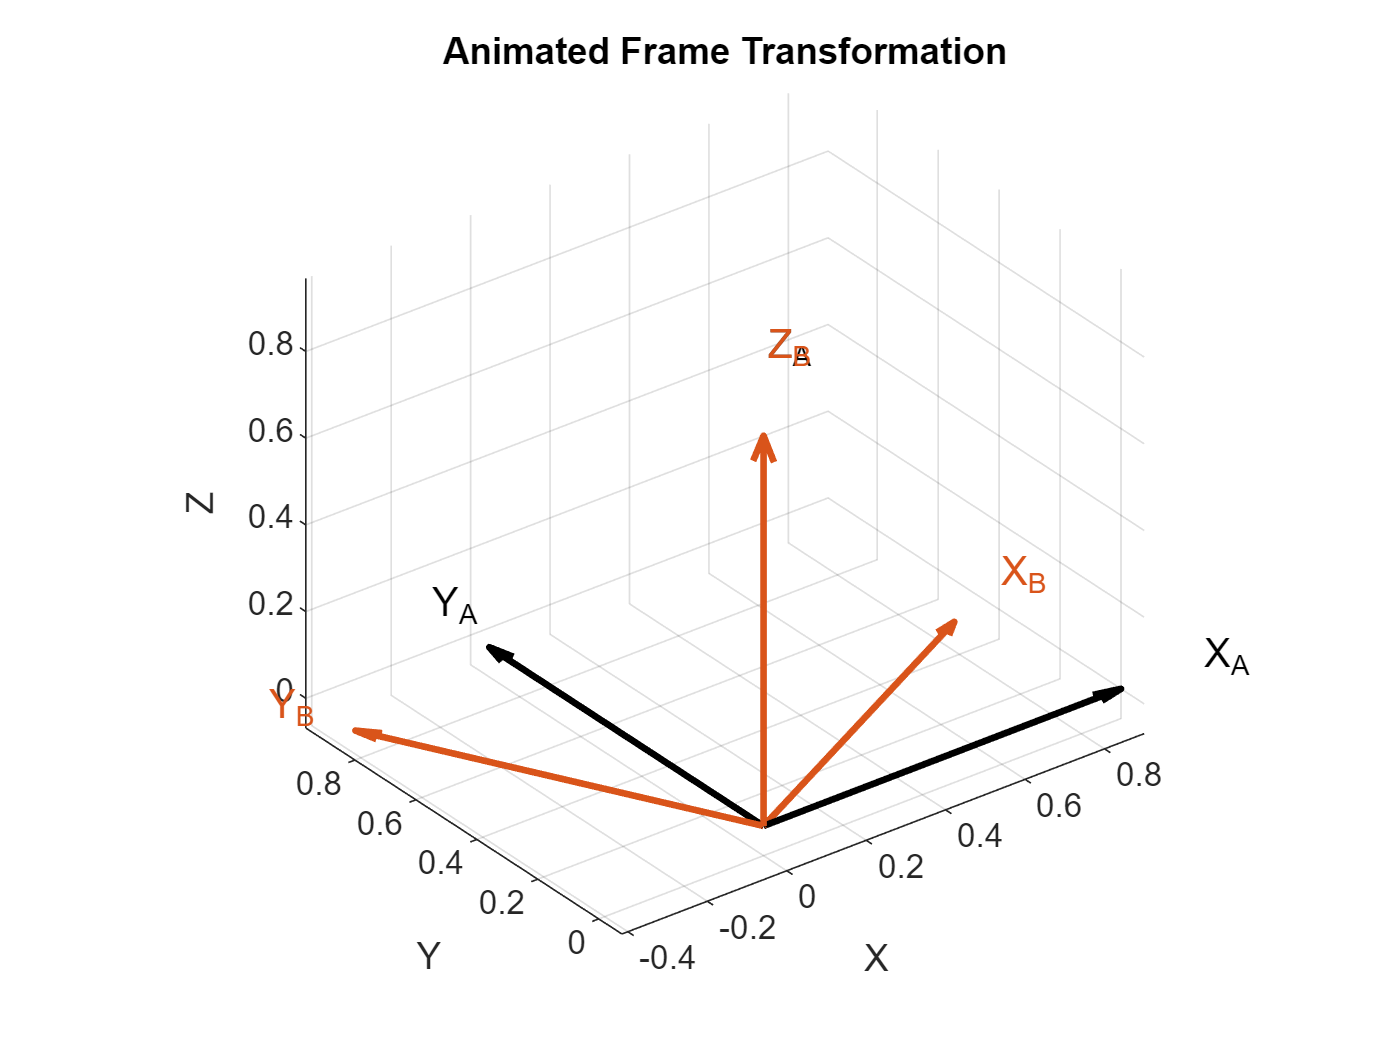

clear; clc; close all;

%% Rotation angles
theta1 = deg2rad(30);   % rotation about Z_B
theta2 = deg2rad(45);   % rotation about X_B

%% Colors
colorA = [0 0 0];          % Frame A: black
colorB = [0.85 0.33 0.1];  % Frame B: orange

%% Plot setup
figure; hold on; grid on; axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Animated Frame Transformation');
view(3);

O = [0 0 0]';

%% Plot Frame A (fixed)
quiver3(0,0,0, 1,0,0, 'Color',colorA,'LineWidth',2);
quiver3(0,0,0, 0,1,0, 'Color',colorA,'LineWidth',2);
quiver3(0,0,0, 0,0,1, 'Color',colorA,'LineWidth',2);
text(1.1,0,0,'X_A','FontSize',12,'Color',colorA)
text(0,1.1,0,'Y_A','FontSize',12,'Color',colorA)
text(0,0,1.1,'Z_A','FontSize',12,'Color',colorA)

%% --- Animation: Rotation about Z_B ---
for t = linspace(0, theta1, 60)
    Rz = [ cos(t) -sin(t) 0;
           sin(t)  cos(t) 0;
           0       0      1 ];

    Bx = Rz(:,1); By = Rz(:,2); Bz = Rz(:,3);

    h = plotFrameWithLabels(Bx, By, Bz, colorB);
    pause(0.03);
    delete(h);
end

%% --- Animation: Rotation about X_B (after Rz) ---
Rz_final = [ cos(theta1) -sin(theta1) 0;
             sin(theta1)  cos(theta1) 0;
             0            0           1 ];

for t = linspace(0, theta2, 60)
    Rx = [ 1 0          0;
           0 cos(t) -sin(t);
           0 sin(t)  cos(t) ];

    R = Rz_final * Rx;

    Bx = R(:,1); By = R(:,2); Bz = R(:,3);

    h = plotFrameWithLabels(Bx, By, Bz, colorB);
    pause(0.03);
    delete(h);
end

%% --- Final frame stays on screen ---
plotFrameWithLabels(Bx, By, Bz, colorB);

legend('Frame A','', '', 'Frame B');


%% Helper function to draw a frame with labels
function h = plotFrameWithLabels(Bx, By, Bz, color)
    h(1) = quiver3(0,0,0, Bx(1),Bx(2),Bx(3), 'Color',color,'LineWidth',2);
    h(2) = quiver3(0,0,0, By(1),By(2),By(3), 'Color',color,'LineWidth',2);
    h(3) = quiver3(0,0,0, Bz(1),Bz(2),Bz(3), 'Color',color,'LineWidth',2);

    % Axis labels positioned slightly beyond arrow tips
    h(4) = text(Bx(1)*1.1, Bx(2)*1.1, Bx(3)*1.1, 'X_B', 'FontSize',12,'Color',color);
    h(5) = text(By(1)*1.1, By(2)*1.1, By(3)*1.1, 'Y_B', 'FontSize',12,'Color',color);
    h(6) = text(Bz(1)*1.1, Bz(2)*1.1, Bz(3)*1.1, 'Z_B', 'FontSize',12,'Color',color);
end
